clear, clc;
data = load("polarPatternsIn.mat");
polarPatternsIn = data.polarPatternsIn;

% General params
fig_size = [0 0 1100 400];
linewidth = 1.5;

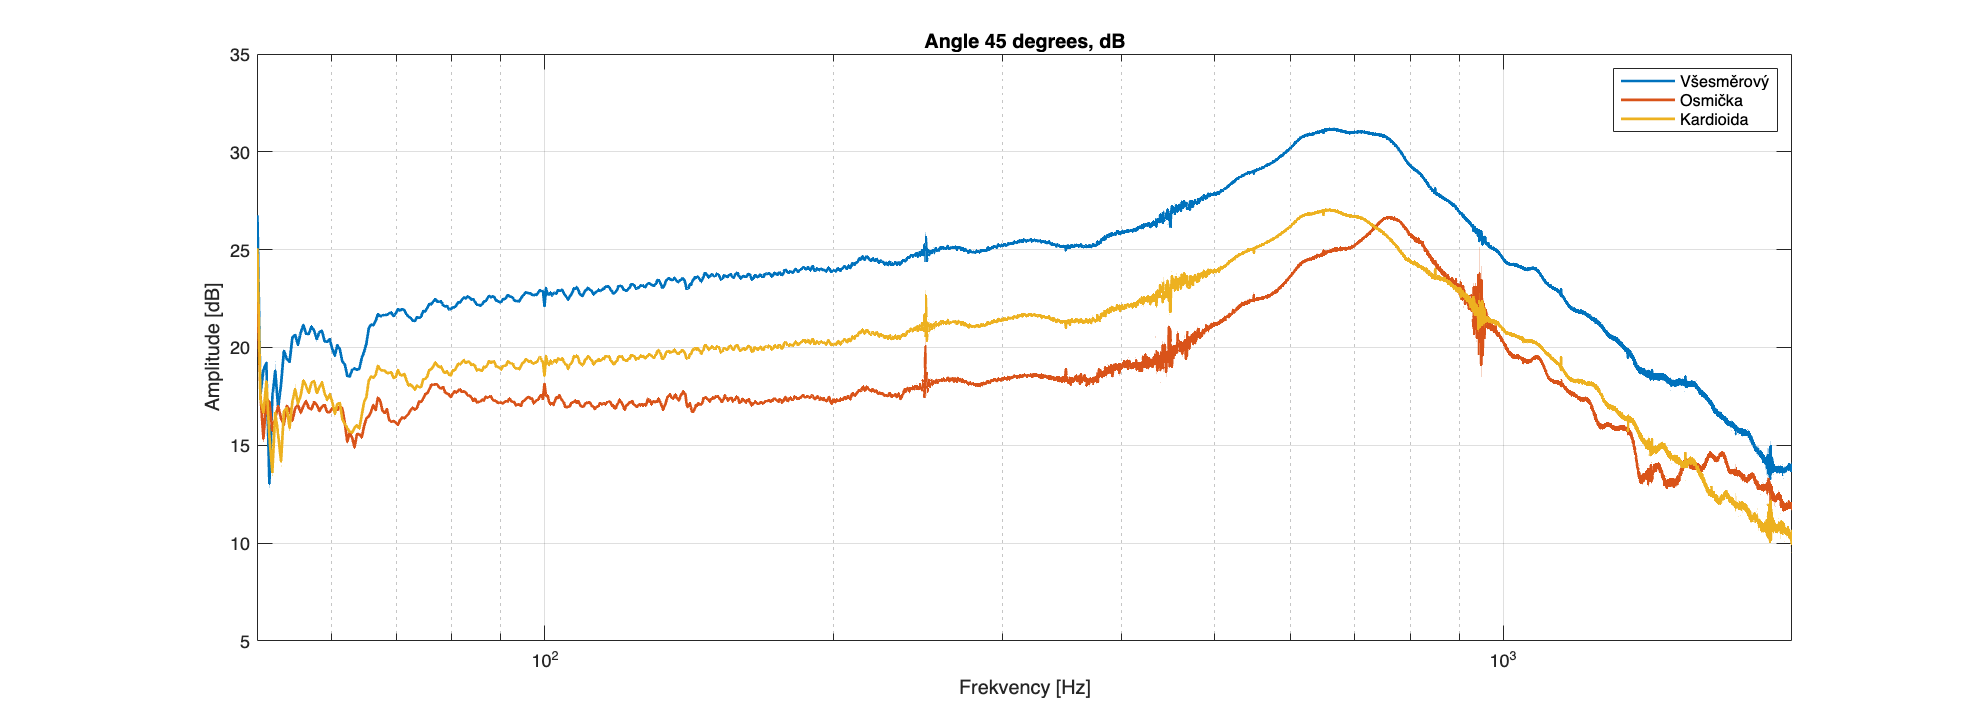

fs = 48000;            % DOSAĎ skutečnou frekvenci měření: ppSampleRate
poloha = 1;            % stejná poloha jako v aplikaci
kanaly = 1:size(polarPatternsIn, 2);

N = size(polarPatternsIn, 1);
f = (0:N-1).' * fs/N;  % frekvence jednotlivých FFT binů

% Dosaď stejný rozsah jako v aplikaci:
fmin = 50;  

fmax = 2000;
vyber = f >= fmin & f <= min(fmax, fs/2);

CH1norm = polarPatternsIn(:,1,:);%/Ratio1to3;
CH2norm = polarPatternsIn(:,2,:);%/Ratio2to4;
CH3norm = polarPatternsIn(:,3,:);%/Ratio3to4;
CH4norm = polarPatternsIn(:,4,:);

polarPatternsOut(:, 1, :) = (CH1norm + CH2norm + CH3norm + CH4norm) / 4; % Všesměrový
polarPatternsOut(:, 2, :) = (CH2norm - CH4norm) / 2; % Osmička
polarPatternsOut(:,3,:) = (polarPatternsOut(:, 1, :) + polarPatternsOut(:, 2, :)) / 2; % Kardioida?

ratio = polarPatternsOut(:, 1, :) ./ polarPatternsOut(:, 2, :);

figure('Position', fig_size);
semilogx(f(vyber), 10*log10(abs(polarPatternsOut(vyber, :, 22))), 'LineWidth', linewidth);
grid on;
xlabel('Frekvency [Hz]');
ylabel('Amplitude [dB]');
title('Angle 45 degrees, dB')
legend(compose(["Všesměrový", "Osmička", "Kardioida"]));

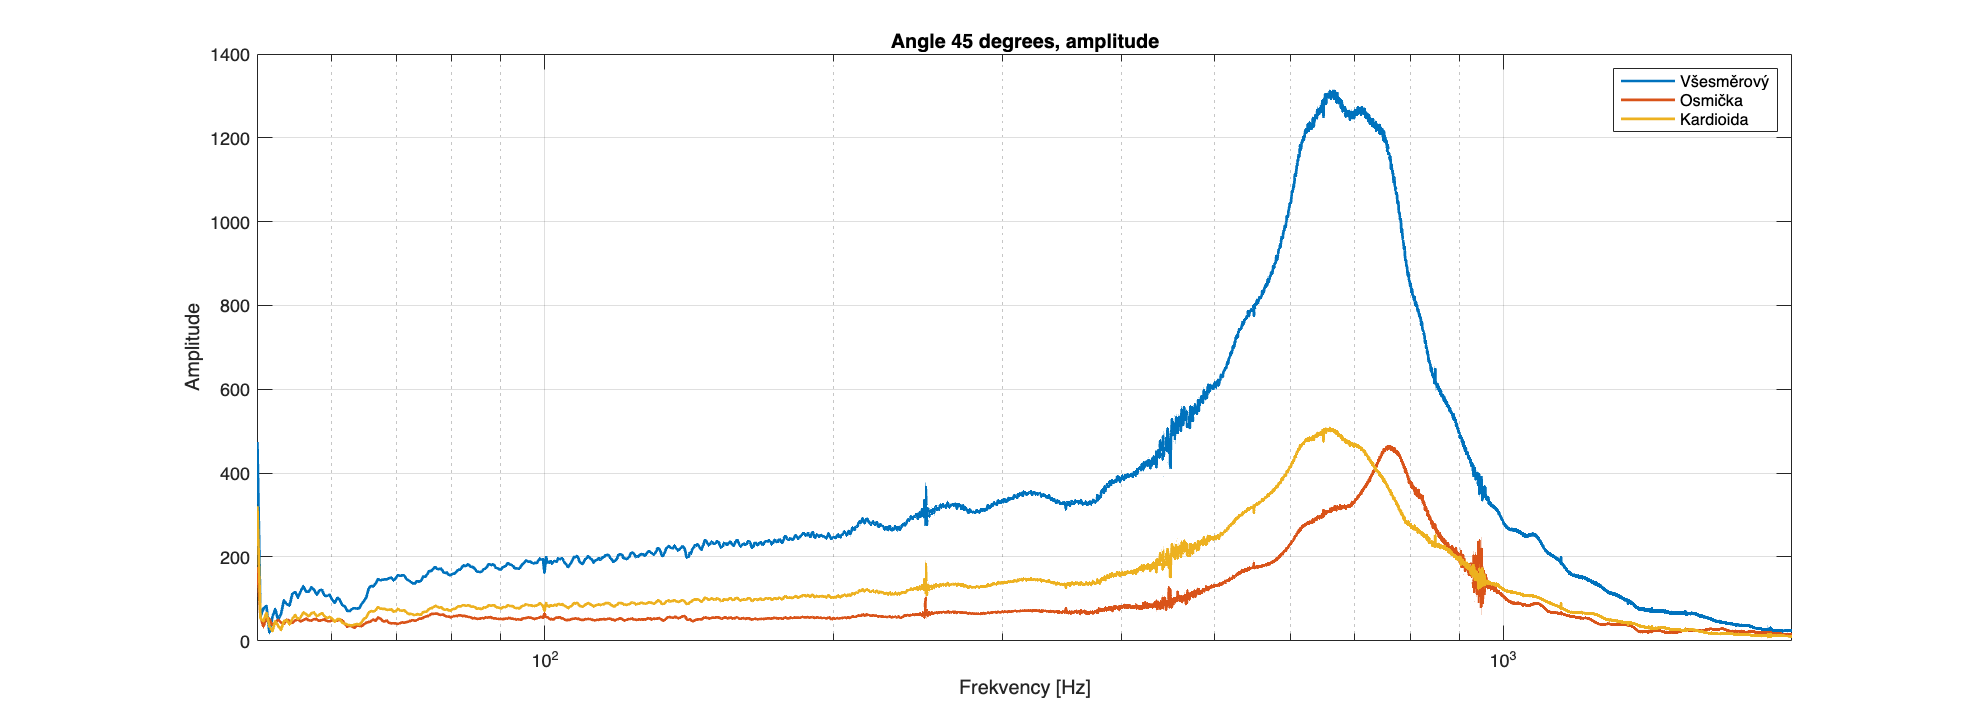


figure('Position', fig_size);
semilogx(f(vyber), abs(polarPatternsOut(vyber, :, 22)), 'LineWidth', linewidth);
grid on;
xlabel('Frekvency [Hz]');
ylabel('Amplitude');
title('Angle 45 degrees, amplitude')
legend(compose(["Všesměrový", "Osmička", "Kardioida"]));

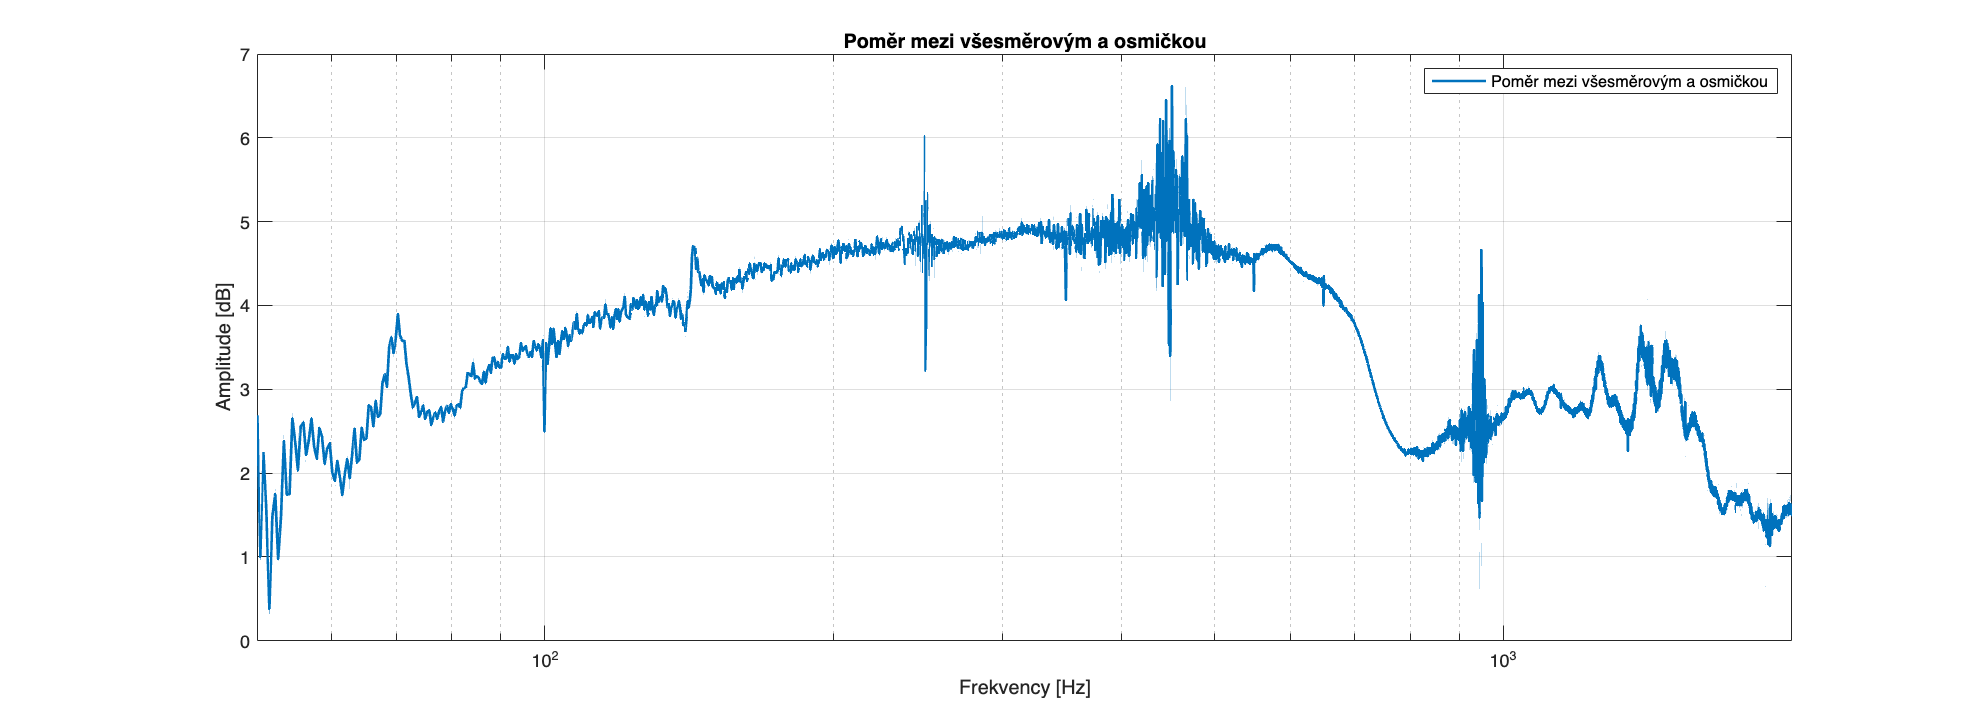


figure('Position', fig_size);
semilogx(f(vyber), abs(ratio(vyber, :, 22)), 'LineWidth', linewidth);
grid on;
xlabel('Frekvency [Hz]');
ylabel('Amplitude [dB]');
title("Poměr mezi všesměrovým a osmičkou")
legend(compose(["Poměr mezi všesměrovým a osmičkou"]));